# Milling and Welding Todo

I have solved for you as an example the drilling task. Similar procedure ought to be done with welding task

See the video: [https://youtu.be/cVZWm9ORY30](https://youtu.be/cVZWm9ORY30)

As you can see in the video a Robot Arm perform three task. Only two tasks are shown: 

- Make a hole in a cylinder by drilling it. Observe that the tool mantain the same orientation during the drilling task.

- Insertion of a smaller cylinder not recorder here. 

- Welding the two cylinder. Observe that the tool always form a 45º among the two cylinder axis

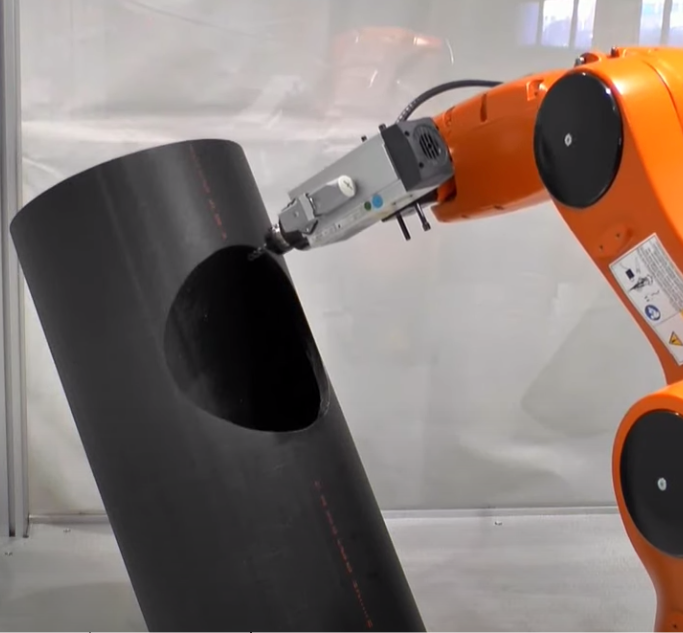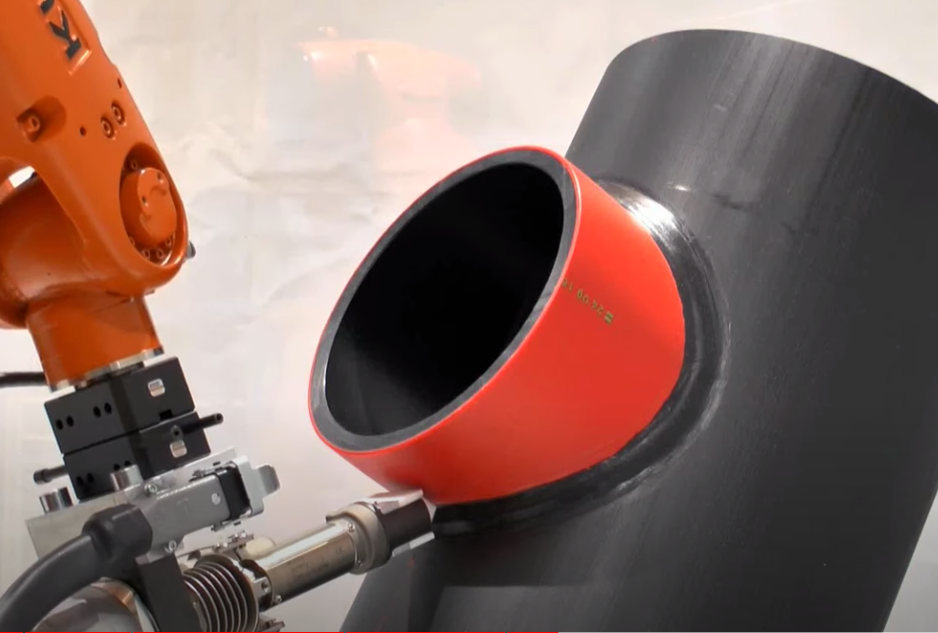

## Load the cylinder data

clear;
close all;
clf
load('F_V_cylinder.mat');

## **Plot the robot to initial position**

Pay attention how to move the robot base and add a tool

radius=0.20;
mdl_puma560
p560.base = transl(-0.1, 0, 0);
p560.tool=transl(0,0,0.15);
%p560.plot(qn,'zoom',2.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],'view',[20 20] );
%hold on

## Visualize the cylinder

Cy_scale=0.25;
%CY_pose=transl([-0.3 0.3 -0.35])*troty(-pi/6) * trotx(-pi/6);
CY_pose_up = transl([0 0 0]) * trotx(pi/4);
CY_pose_down = transl([0 0 0]) * trotx(-pi/4);


## Draw drill task profile

Drill hole center 'D_h_c'

D_h_c_up = CY_pose_up;
D_h_c_down = CY_pose_down;

D_h_c = transl([0 0 0]);

D_h_c_face_up = transl([0,0.1,0.1]) * CY_pose_up;

Drill poses

n = 16;
N = 32;
for i=1:n
%Drill_Pose(:,:,i)= D_h_c_up * trotz(pi*i/n) * transl(radius, 0,0) * troty(-pi/2) * trotz(-pi/4);
    Drill_Pose(:,:,i) = D_h_c * trotz(pi*i/n) * transl(radius, 0,0);
    Drill_Pose(:,:,i) = Drill_Pose(:,:,i) * troty(pi/4) * transl(-radius,0,0);
end

for i=n+1:N
%Drill_Pose(:,:,i)= D_h_c_down * trotz(pi*i/n) * transl(radius, 0,0) * troty(-pi/2) * trotz(-pi/4);
%Drill_Pose(:,:,i)= D_h_c_down * trotz(pi*i/n) * transl(radius, 0,0);
end

r=15.6; % Tube radius
t=0:pi/16:2*pi; % Scan variable
cp0=[r*cos(t);
     r*sin(t);
     abs(r*cos(t));
     ones(1,length(t))];

n = 32;
r = radius;
for i=1:n
    t = (i-1)*pi/16;
    Drill_Pose(:,:,i) = D_h_c * transl(r*cos(t), r*sin(t), abs(r*cos(t))) * trotz(2*pi*(i-1)/n) * troty(pi/4) * trotx(pi);
end

%%%%%%%% Drill_Pose(:,:,i)= D_h_c * trotz(2*pi*i/n) * transl(radius, 0,0) * troty(-pi/4);

%scatter3(cp0(1,:),cp0(2,:),cp0(3,:),'r','LineWidth',2)
%xyzlabel% RTB

Plotting Drill poses. Notice 'z' axis of the poses 

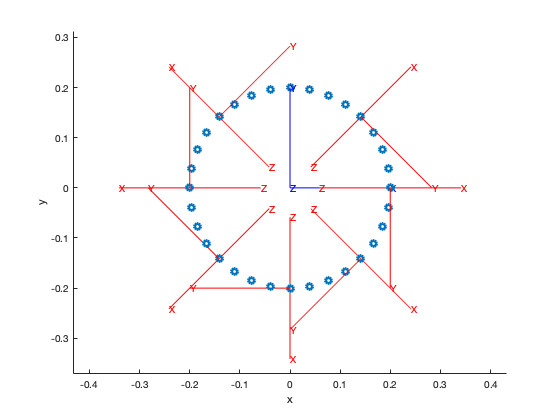

cir=transl(Drill_Pose)';
hold on
plot3(cir(1,:), cir(2,:), cir(3,:), 'o', 'LineWidth', 3);
xyzlabel
axis equal

trplot(D_h_c, 'length', 0.2)
%trplot(D_h_c_face_up(:,:,1), 'length', 0.2, 'color', 'g')
%for i=1:n
%    trplot(Drill_Pose(:,:,i), 'length', 0.2, 'color', 'r')
%end

trplot(Drill_Pose(:,:,1), 'length', 0.2, 'color', 'r')
trplot(Drill_Pose(:,:,5), 'length', 0.2, 'color', 'r')
trplot(Drill_Pose(:,:,13), 'length', 0.2, 'color', 'r')
trplot(Drill_Pose(:,:,17), 'length', 0.2, 'color', 'r')
trplot(Drill_Pose(:,:,21), 'length', 0.2, 'color', 'r')
trplot(Drill_Pose(:,:,25), 'length', 0.2, 'color', 'r')
trplot(Drill_Pose(:,:,29), 'length', 0.2, 'color', 'r')

## Functions

function T_b_a=FVsPlot(F,V,color)
patch('Faces',F,'Vertices',V,'FaceColor',color, ...
         'FaceAlpha',0.8,...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

grid on
xlabel 'X [mm]'
ylabel 'Y [mm]'
zlabel 'Z [mm]'
axis equal
end

